# PhysioNet Challenge

2023-10-01

url = "https://physionet.org/files/i-care/2.0/training/";

% Specify the URL
records_url = 'https://physionet.org/files/i-care/2.0/training/RECORDS';

% r = readtable(records_url)

% Read the content from the web
data = webread(records_url);

% Split the content by newline to get a cell array of strings
paths = strsplit(data, '\n');

% Remove empty cells, if any, from the cell array
paths = paths(~cellfun('isempty', paths));

% Initialize a cell array to hold the modified paths
patients = cell(size(paths));

% Loop over each path and perform the replacement operation
for i = 1:length(paths)
    patients{i} = regexprep(paths{i}, 'training', '');
    patients{i} = regexprep(patients{i}, '/', '');
end

% Display the original and modified paths
T = table(paths', patients', 'VariableNames', {'Path', 'Patient'});
% disp(T);
T

T = 607×2 table
           Path           Patient 
    __________________    ________

    {'training/0284/'}    {'0284'}
    {'training/0286/'}    {'0286'}
    {'training/0296/'}    {'0296'}
    {'training/0299/'}    {'0299'}
    {'training/0303/'}    {'0303'}
    {'training/0306/'}    {'0306'}
    {'training/0311/'}    {'0311'}
    {'training/0312/'}    {'0312'}
    {'training/0313/'}    {'0313'}
    {'training/0316/'}    {'0316'}
    {'training/0319/'}    {'0319'}
    {'training/0320/'}    {'0320'}
    {'training/0326/'}    {'0326'}
    {'training/0328/'}    {'0328'}
    {'training/0332/'}    {'0332'}
    {'training/0334/'}    {'0334'}


patient = "0284";
% readtable(url+patient+"/RECORDS")
data = webread(url+patient+"/RECORDS");
data

data =     '0284_001_004_ECG
     0284_001_004_EEG
     0284_001_004_OTHER
     0284_002_005_ECG
     0284_002_005_EEG
     0284_002_005_OTHER
     0284_003_006_ECG
     0284_003_006_EEG
     0284_003_006_OTHER
     0284_004_007_ECG
     0284_004_007_EEG
     0284_004_007_OTHER
     0284_005_008_ECG
     0284_005_008_EEG
     0284_005_008_OTHER
     0284_006_008_ECG
     0284_006_008_EEG
     0284_006_008_OTHER
     0284_007_009_ECG
     0284_007_009_EEG
     0284_007_009_OTHER
     0284_008_010_ECG
     0284_008_010_EEG
     0284_008_010_OTHER
     0284_009_011_ECG
     0284_009_011_EEG
     0284_009_011_OTHER
     0284_010_012_ECG
     0284_010_012_EEG
     0284_010_012_OTHER
     0284_011_012_ECG
     0284_011_012_EEG
     0284_011_012_OTHER
     0284_012_013_ECG
     0284_012_013_EEG
     0284_012_013_OTHER
     0284_013_014_ECG
     0284_013_014_EEG
     0284_013_014_OTHER
     0284_014_015_ECG
     0284_014_015_EEG
     0284_014_015_OTHER
     0284_015_016_ECG
     0284_015_016_E

patient_0284 = webread(url+patient+"/"+patient+".txt")

patient_0284 =     'Patient: 0284
     Hospital: A
     Age: 53
     Sex: Male
     ROSC: nan
     OHCA: True
     Shockable Rhythm: True
     TTM: 33
     Outcome: Good
     CPC: 1
     '


filename = "0284_001_004_ECG.mat";

filename = "0284_001_004_ECG.mat"

websave("training/"+patient+"/"+filename,url+patient+"/"+filename)

ans = '/MATLAB Drive/physionet/training/0284/0284_001_004_ECG.mat'

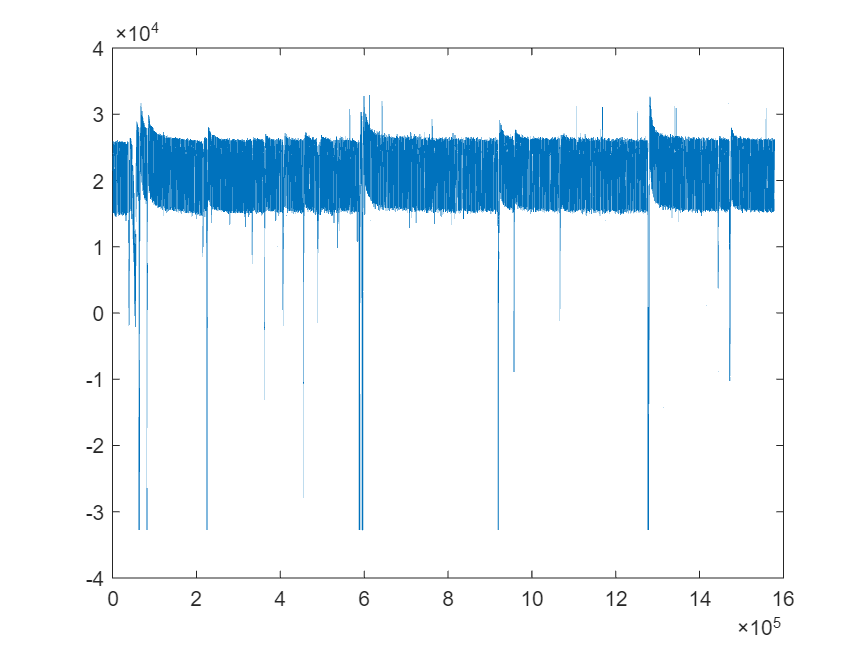

plot(val)